# Lab4

dt = 0.01;
df = dt;
t = -10 : dt : 10;
f = -15 : df : 15;

## Esercizio 2 (i)

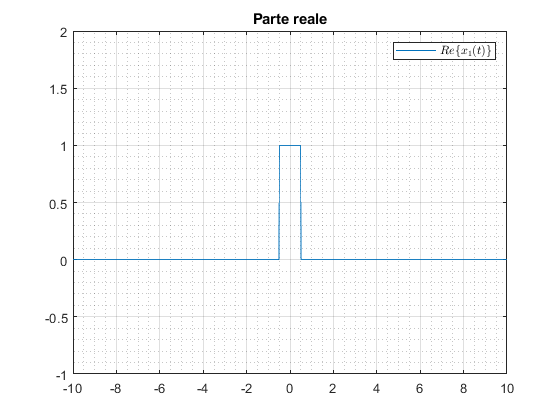

x1 = rect(t);
X1 = trasformataDiFourier(t, x1, f);
rappresentaUnSegnale(t, x1, 'x_{1}(t)');

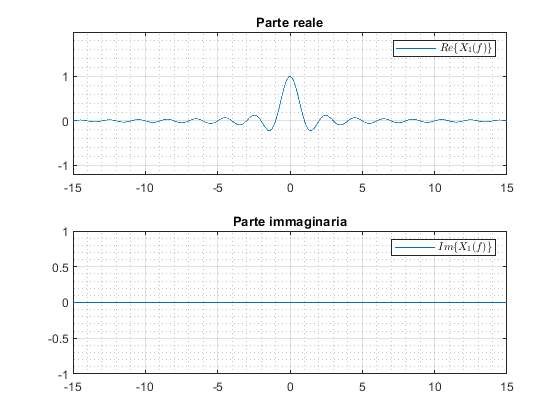

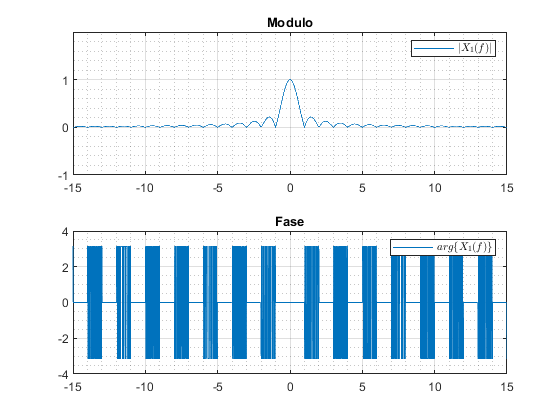

rappresentaUnSegnale(f, X1, 'X_{1}(f)');

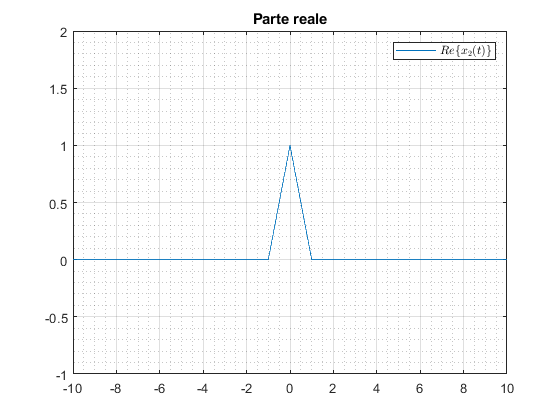

x2 = tri(t);
X2 = trasformataDiFourier(t, x2, f);
rappresentaUnSegnale(t, x2, 'x_{2}(t)');

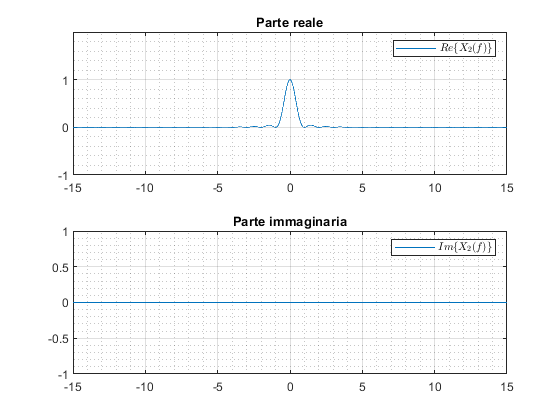

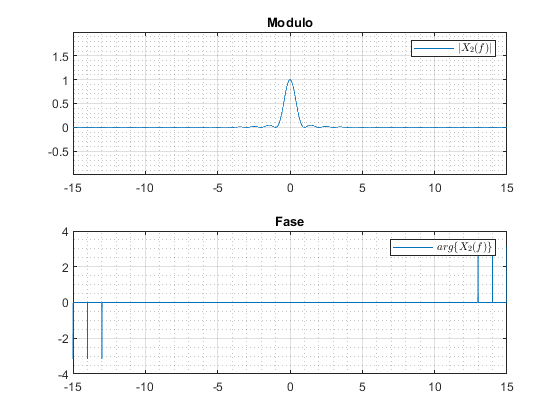

rappresentaUnSegnale(f, X2, 'X_{2}(f)');

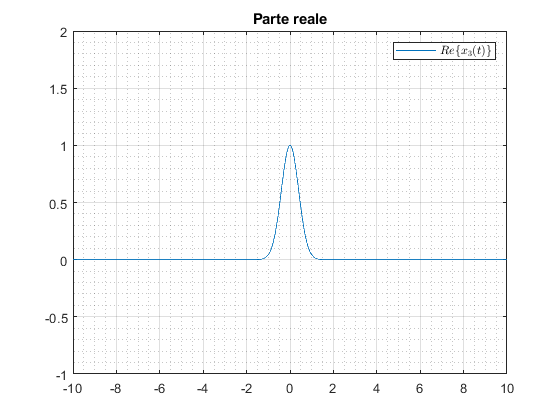

x3 = exp(-pi * t.^2);
X3 = trasformataDiFourier(t, x3, f);
rappresentaUnSegnale(t, x3, 'x_{3}(t)');

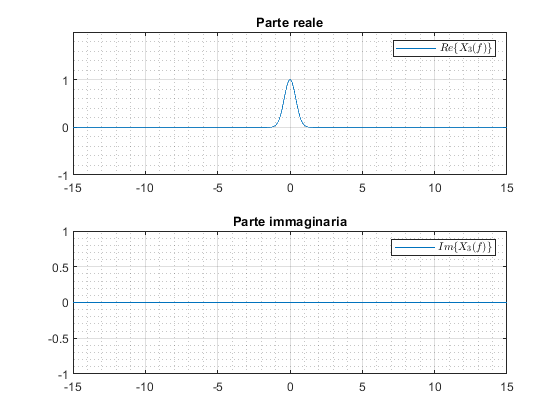

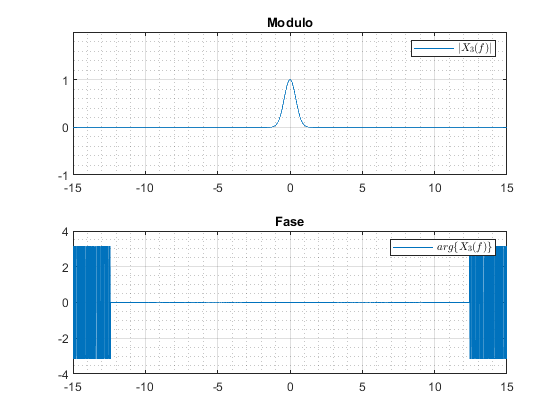

rappresentaUnSegnale(f, X3, 'X_{3}(f)');

## Esercizio 2 (ii)

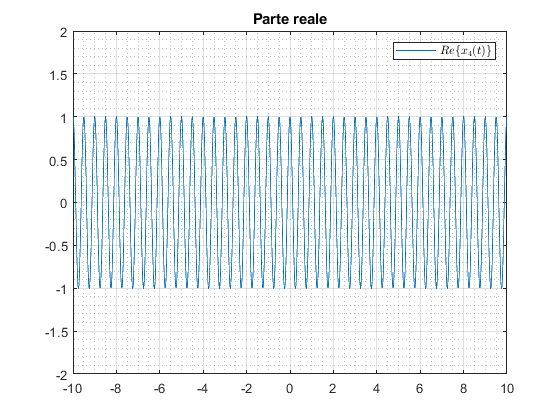

x4 = cos(4 * pi * t);
X4 = trasformataDiFourier(t, x4, f);
rappresentaUnSegnale(t, x4, 'x_{4}(t)');

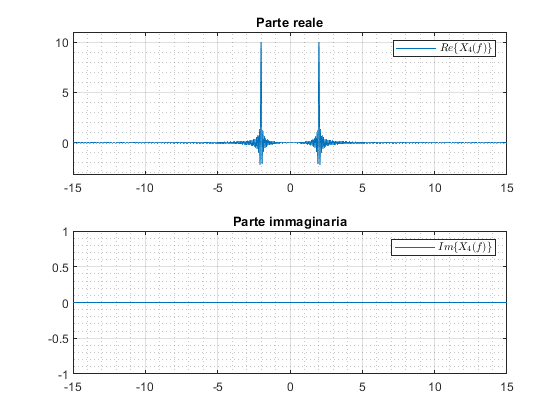

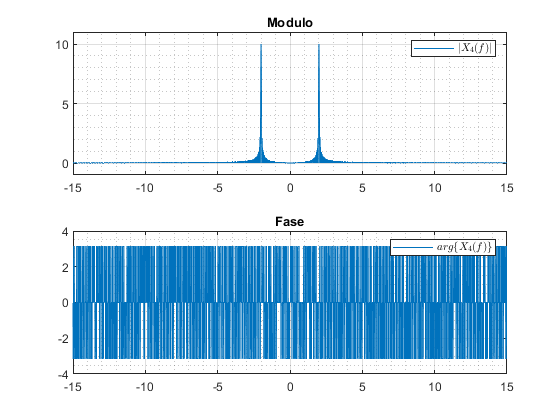

rappresentaUnSegnale(f, X4, 'X_{4}(f)');

## Esercizio 3 (i)

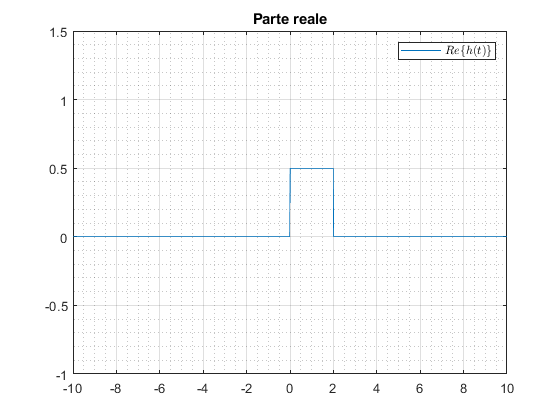

T = 2;
h = 1 / T * rect((t - T / 2) / T);
H = trasformataDiFourier(t, h, f);
rappresentaUnSegnale(t, h, 'h(t)');

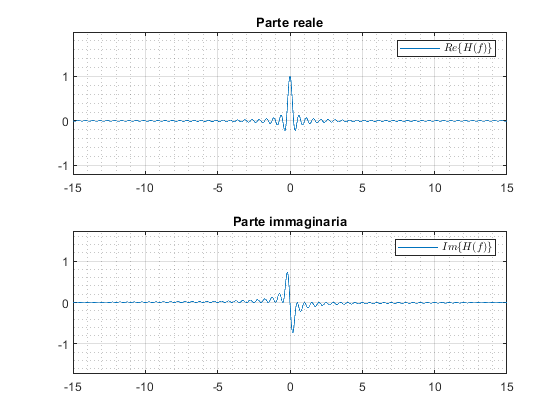

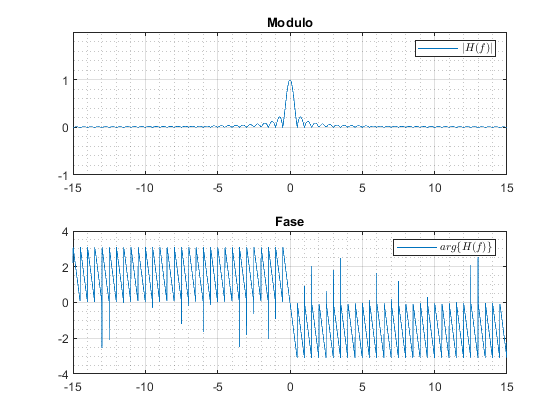

rappresentaUnSegnale(f, H, 'H(f)');

## Esercizio 3 (ii)

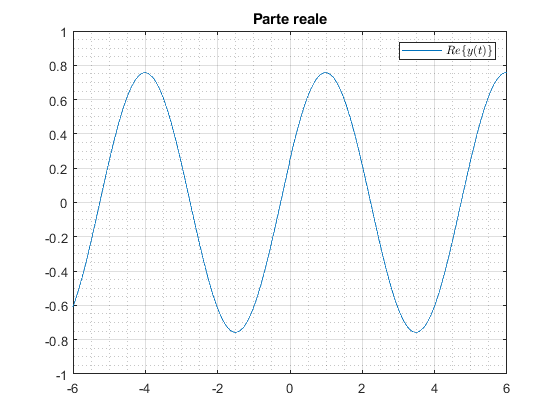

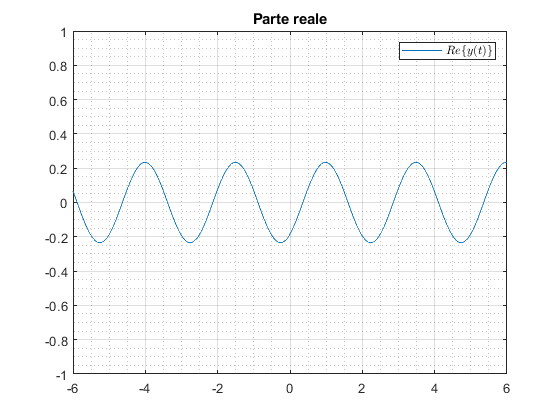

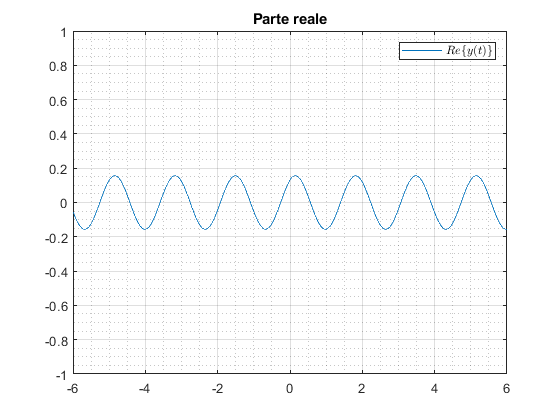

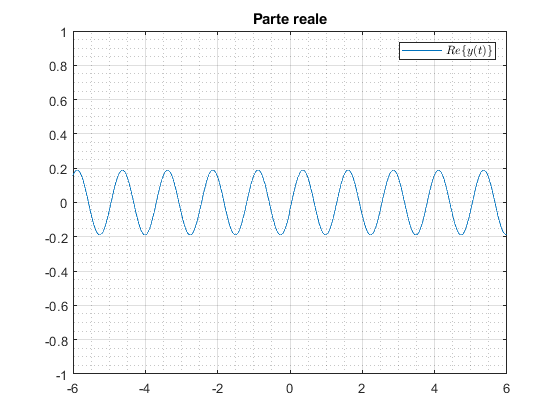

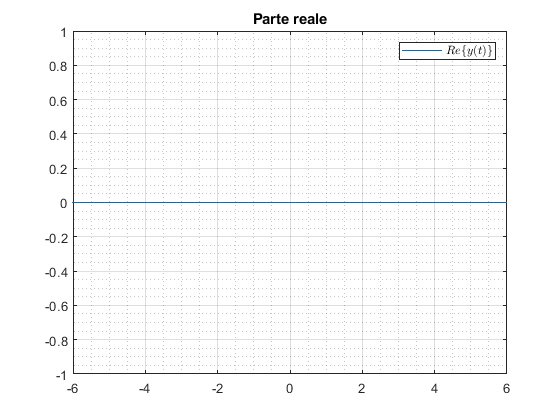

A = 1;
for f0 = 0.2:0.2:1
	x = A * cos(2 * pi * f0 * t);
	y = convoluzione(t, x, h);
	rappresentaUnSegnale(y(1, :), y(2, :), 'y(t)');
	axis([-6 6 -1 1]);
end